# ODE Lab: Creating your own ODE solver in MATLAB

In this lab, you will write your own ODE solver for the Improved Euler method (also known as the Heun method), and compare its results to those of `ode45`.

You will also learn how to write a function in a separate m-file and execute it.

Opening the m-file lab3.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are six (6) exercises in this lab that are to be handed in on the due date. Write your solutions in the template, including appropriate descriptions in each step. Save the .m files and submit them online on Quercus.

## Student Information

Student Name: 1008107683

Student Number: Linda Zhao

## Creating new functions using m-files.

Create a new function in a separate m-file:

Specifics: Create a text file with the file name f.m with the following lines of code (text):

Now MATLAB can call the new function f (which simply accepts 3 numbers and adds them together). To see how this works, type the following in the matlab command window: sum = f(1,2,3)

## Exercise 1

Objective: Write your own ODE solver (using the Heun/Improved Euler Method).

Details: This m-file should be a function which accepts as variables (t0,tN,y0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0 is the initial condition of the ODE, and h is the stepsize. You may also want to pass the function into the ODE the way `ode45` does (check lab 2).

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

## Exercise 2

Objective: Compare Heun with `ode45`.

Specifics: For the following initial-value problems (from lab 2, exercises 1, 4-6), approximate the solutions with your function from exercise 1 (Improved Euler Method). Plot the graphs of your Improved Euler Approximation with the `ode45` approximation.

(a) `y' = y tan t + sin t, y(0) = -1/2` from `t = 0` to `t = pi`

(b) `y' = 1 / y^2 , y(1) = 1` from `t=1` to `t=10`

(c) `y' = 1 - t y / 2, y(0) = -1` from `t=0` to `t=10`

(d) `y' = y^3 - t^2, y(0) = 1` from `t=0` to `t=1`

Comment on any major differences, or the lack thereof. You do not need to reproduce all the code here. Simply make note of any differences for each of the four IVPs.

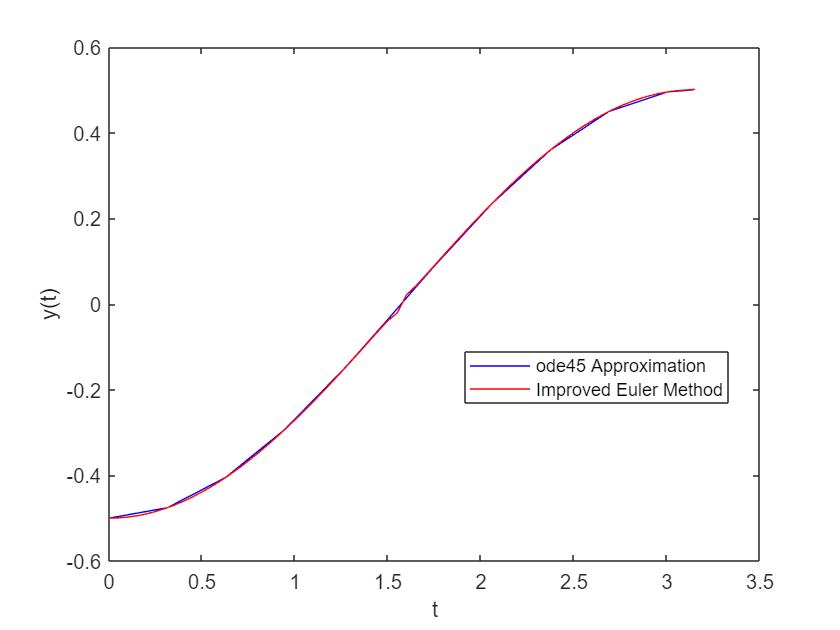

% (a) y' = y tan t + sin t, y(0) = -1/2 from t = 0 to t = pi
fa = @(t, y) y*tan(t) + sin(t);

t0_a = 0;
tN_a = pi;
y0_a = -0.5;

a_ode45 = ode45(fa, [t0_a, tN_a], y0_a);
[a_IEM_x, a_IEM_y] = IEM_solver(fa, t0_a, tN_a, y0_a, 0.05);

plot(a_ode45.x, a_ode45.y, 'b', a_IEM_x, a_IEM_y, 'r');
legend("ode45 Approximation", "Improved Euler Method", 'Location', 'best')
xlabel("t")
ylabel("y(t)")

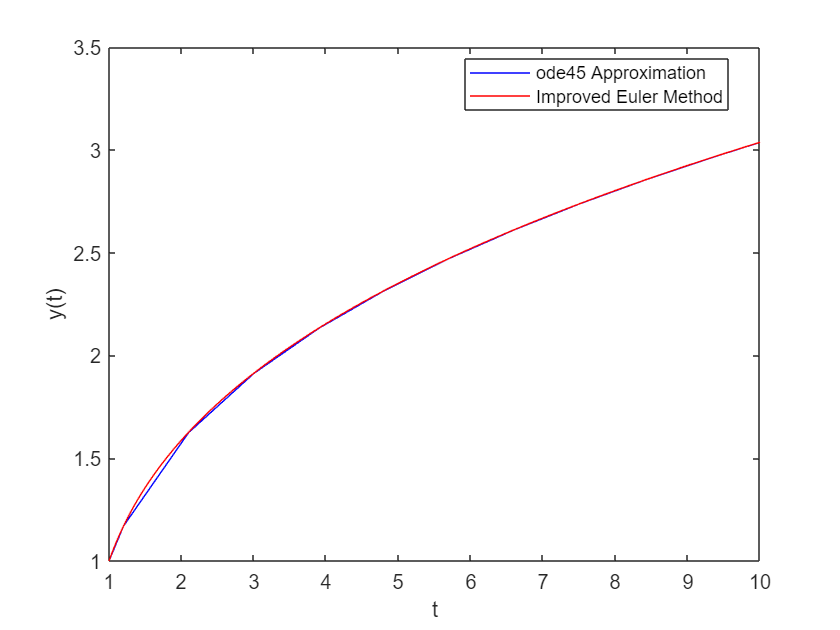


% Major differences: The solution given by my IEM solver sees a sharp jump
% (and increase in error) at around pi/2. This is likely because, as the
% IEM solver approaches pi/2, the slope (given by y+tan(t) + sin(t)) becomes
% very large, causing the solver to take a large jump. This issue is less
% prevalent with ode45 because it has adaptive step sizes, and likely takes
% much smaller steps around t = pi/2. 

% (b) y' = 1 / y^2 , y(1) = 1 from t=1 to t=10
fb = @(t, y) 1 / y^2;

t0_b = 1;
tN_b = 10;
y0_b = 1;

b_ode45 = ode45(fb, [t0_b, tN_b], y0_b);
[b_IEM_x, b_IEM_y] = IEM_solver(fb, t0_b, tN_b, y0_b, 0.05);

plot(b_ode45.x, b_ode45.y, 'b', b_IEM_x, b_IEM_y, 'r');
legend("ode45 Approximation", "Improved Euler Method", 'Location', 'best')
xlabel("t")
ylabel("y(t)")

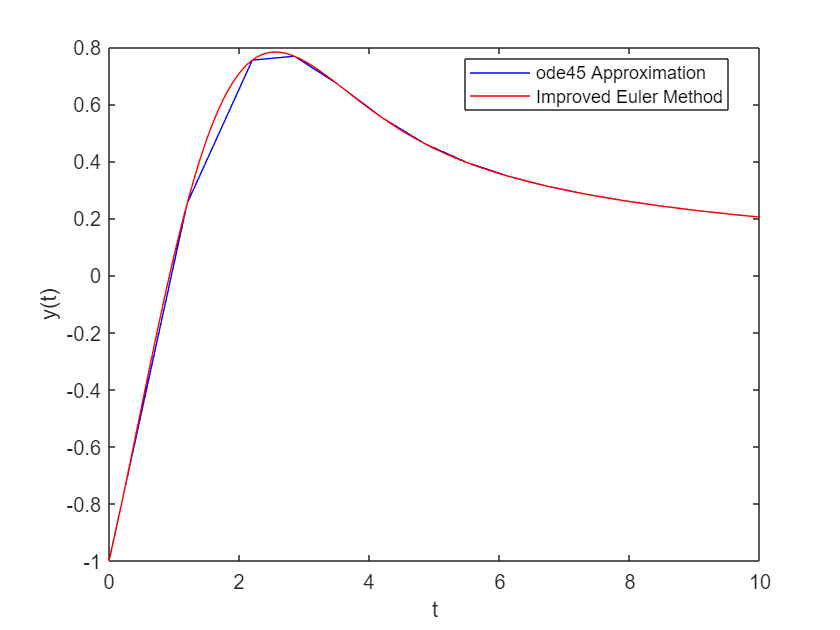


% Major differences: The IEM solver produces a smoother curve for smaller
% t; this is likely because the step size I chose is smaller than the step
% size that ode45 chooses. 

% (c) y' = 1 - t y / 2, y(0) = -1 from t=0 to t=10
fc = @(t, y) 1 - t*y/2;

t0_c = 0;
tN_c = 10;
y0_c = -1;

c_ode45 = ode45(fc, [t0_c, tN_c], y0_c);
[c_IEM_x, c_IEM_y] = IEM_solver(fc, t0_c, tN_c, y0_c, 0.05);


plot(c_ode45.x, c_ode45.y, 'b', c_IEM_x, c_IEM_y, 'r');
legend("ode45 Approximation", "Improved Euler Method", 'Location', 'best')
xlabel("t")
ylabel("y(t)")

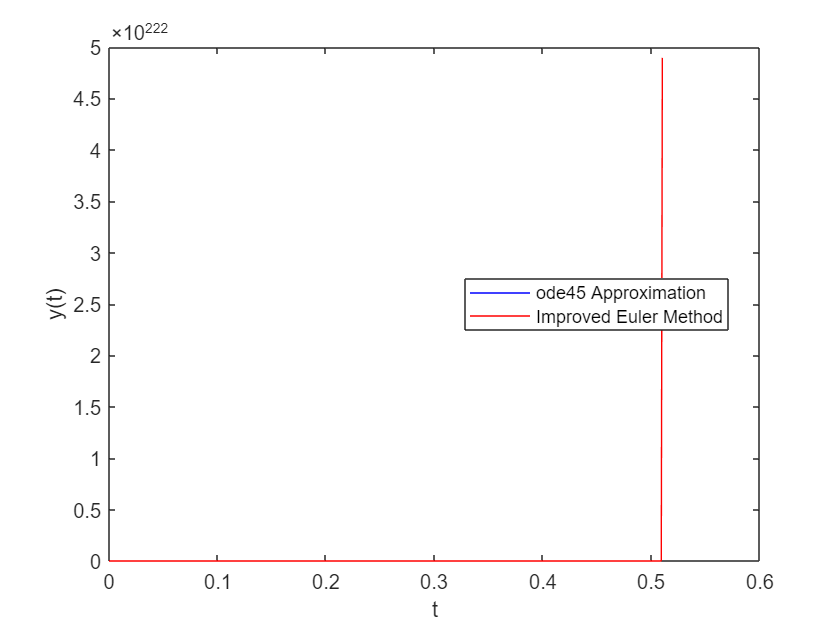


% Major differences: The IEM solver produces a smoother curve for smaller
% t (especially around t = 1 to t = 3); this is likely because the step size I
% chose is smaller than the step size that ode45 chooses.

% (d) y' = y^3 - t^2, y(0) = 1 from t=0 to t=1
fd = @(t, y) y^3 - t^2;

t0_d = 0;
tN_d = 10;
y0_d = 1;

d_ode45 = ode45(fd, [t0_d, tN_d], y0_d);
[d_IEM_x, d_IEM_y] = IEM_solver(fd, t0_d, tN_d, y0_d, 0.001);

plot(d_ode45.x, d_ode45.y, 'b', d_IEM_x, d_IEM_y, 'r');
legend("ode45 Approximation", "Improved Euler Method", 'Location', 'best')
xlabel("t")
ylabel("y(t)")


% Major differences: Upon decreasing the step size for the IEM solver, both
% ode45 and the IEM solver seem to produce similar solutions, with both
% diverging to infinity after t = 0.50 and before t = 0.55. However, if I
% were to use the same step size as I did for the previous parts, the IEM
% solver would produce a solution that diverged to infinity slightly later
% than the one produced by ode45. One thing to note is that ode45 gives a
% warning that it is unable to meet integration tolerances.

## Exercise 3

Objective: Use Euler's method and verify an estimate for the global error.

Details: 

(a) Use Euler's method (you can use euler.m from iode) to solve the IVP

`y' = 2 t sqrt( 1 - y^2 ) , y(0) = 0`

from `t=0` to `t=0.5`.

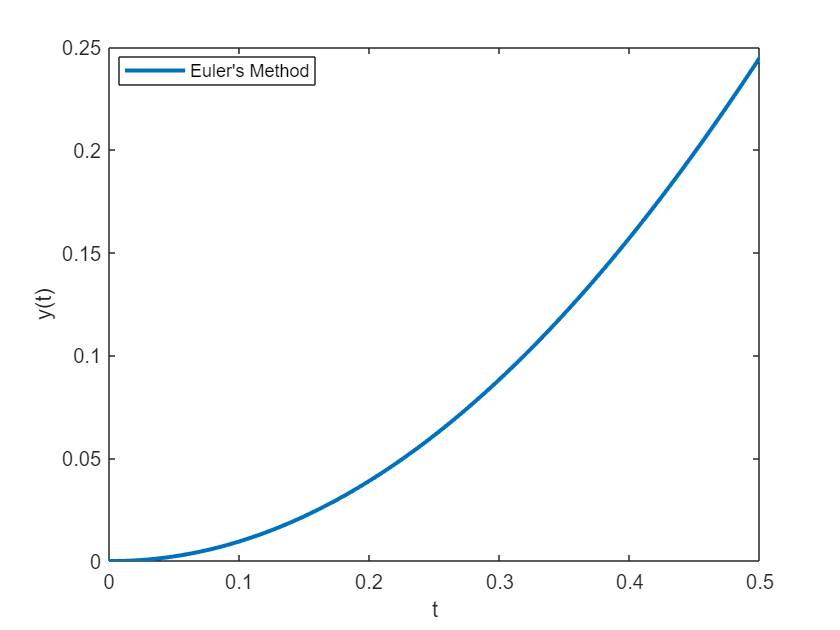

f = @(t, y) 2 * t * sqrt(1-y^2); % Define inline function
tvals = 0:0.005:0.5; % Create t vector
euler_y = euler(f, 0, tvals); % Use euler to solve IVP using a step size of 0.01
plot(tvals, euler_y, 'LineWidth', 2) % Plot solution
legend("Euler's Method", 'Location', 'best')
xlabel("t")
ylabel("y(t)")

(b) Calculate the solution of the IVP and evaluate it at `t=0.5`.

% IVP Solution: y(t) = sin(t^2);
y = @(t) sin(t^2);
y_05 = y(0.5)

y_05 = 0.2474

(c) Read the attached derivation of an estimate of the global error for Euler's method. Type out the resulting bound for En here in a comment. Define each variable.

% E_n = ((1+M)*dt/2)*(exp(M*dt*n)-1), where:
% M is the upper bound of f, df/dt, and df/dy, which is 2 for the above IVP
% dt is the (time) step size, which is ~0.005 for the above
% n is the number of steps taken, which is 100 for the above

(d) Compute the error estimate for `t=0.5` and compare with the actual error.

M = 2;
n = 100;
dt = 0.005;

error_estimate_1 = ((1+M)*dt/2)*(exp(M*dt)-1)*n % Compute E_n using above equation

error_estimate_1 = 0.0075

actual_error_1 = abs(sin(0.5^2) - euler_y(n)) % Compute actual error

actual_error_1 = 0.0072

(e) Change the time step and compare the new error estimate with the actual error. Comment on how it confirms the order of Euler's method.

tvals = 0:0.001:0.5;
euler_y_2 = euler(f, 0, tvals);
M = 2;
n = 500;
dt = 0.001;

error_estimate_2 = ((1+M)*dt/2)*(exp(M*dt)-1)*n % Compute E_n using above equation

error_estimate_2 = 0.0015

actual_error_2 = abs(sin(0.5^2) - euler_y_2(n)) % Compute actual error

actual_error_2 = 0.0014


% The error for large n values is expected to be proportional to dt as dt -> 0.
% Since I decreased dt by a factor of 5 (i.e. from 0.005 to 0.001), the error
% estimate also reduced by a factor of 5 (i.e. from 0,0075 to 0.0015).

## Adaptive Step Size

As mentioned in lab 2, the step size in `ode45` is adapted to a specific error tolerance.

The idea of adaptive step size is to change the step size `h` to a smaller number whenever the derivative of the solution changes quickly. This is done by evaluating f(t,y) and checking how it changes from one iteration to the next.

## Exercise 4

Objective: Create an Adaptive Euler method, with an adaptive step size `h`.

Details: Create an m-file which accepts the variables `(t0,tN,y0,h)`, as in exercise 1, where `h` is an initial step size. You may also want to pass the function into the ODE the way `ode45` does.

Create an implementation of Euler's method by modifying your solution to exercise 1. Change it to include the following:

(a) On each timestep, make two estimates of the value of the solution at the end of the timestep: `Y` from one Euler step of size `h` and `Z` from two successive Euler steps of size `h/2`. The difference in these two values is an estimate for the error.

(b) Let `tol=1e-8` and `D=Z-Y`. If `abs(D)<tol`, declare the step to be successful and set the new solution value to be `Z+D`. This value has local error `O(h^3)`. If `abs(D)>=tol`, reject this step and repeat it with a new step size, from (c).

(c) Update the step size as `h = 0.9*h*min(max(tol/abs(D),0.3),2)`.

Comment on what the formula for updating the step size is attempting to achieve.

% The formula for updating the step size attempts to ensure that, by taking
% a step of size h, the error of the result will be within the tolerance
% range defined as tol= = 1e-8. If the error is much greater than the
% tolerance, then the step size will be reduced greatly (by a factor of
% 0.9*0.3), whereas if the error is near the tolerance, the step size will
% be reduced by a much smaller factor. 0.9 represents the default scaling
% factor for h. 

## Exercise 5

Objective: Compare Euler to your Adaptive Euler method.

Details: Consider the IVP from exercise 3.

(a) Use Euler method to approximate the solution from `t=0` to `t=0.75` with `h=0.025`.

t0 = 0;
tN = 0.75;
y0 = 0;
h = 0.025;

f = @(t, y) 2 * t * sqrt(1-y^2); % (re)Define inline function
tvals = t0:h:tN; % Create t vector
euler_y = euler(f, 0, tvals); % Use euler to solve IVP using a step size of 0.01

(b) Use your Adaptive Euler method to approximate the solution from `t=0` to `t=0.75` with initial `h=0.025`.

[AEM_t, AEM_y] = AEM_solver(f, t0, tN, y0, h);

(c) Plot both approximations together with the exact solution.

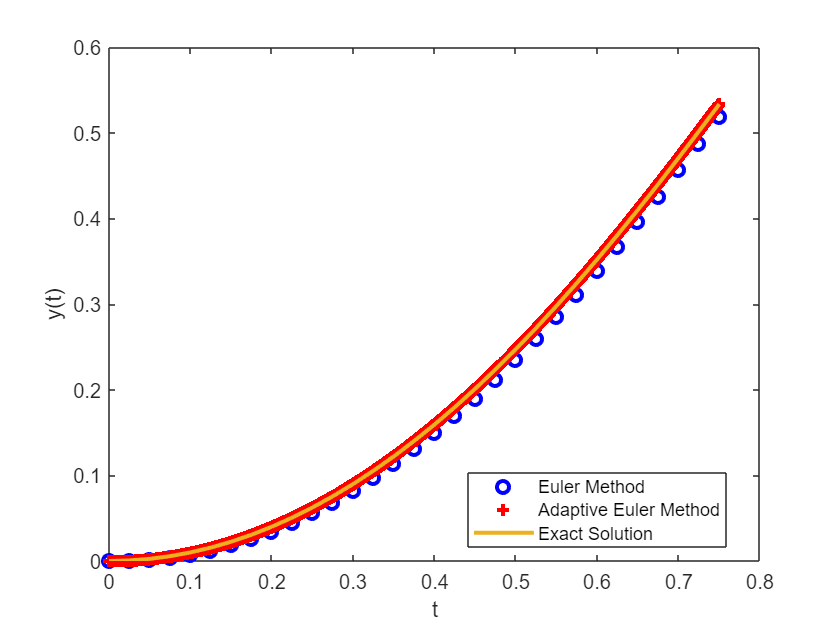

plot(tvals, euler_y, 'bo', AEM_t, AEM_y, 'r+', tvals, sin(tvals.^2), 'LineWidth', 2)
legend("Euler Method", "Adaptive Euler Method", "Exact Solution", Location="best")
xlabel("t")
ylabel("y(t)")

## Exercise 6

Objective: Problems with Numerical Methods.

Details: Consider the IVP from exercise 3 (and 5).

(a) From the two approximations calculated in exercise 5, which one is closer to the actual solution (done in 3.b)? Explain why.

% The AEM approximation is much closer to the exact solution. This is
% because, to get to the AEM approximation, many more steps were taken when
% compared to Euler's method. This can be observed by the length of the
% respective solution vectors in the MATLAB workspace; the AEM solution
% involves 5600+ individual steps, whereas the euler solution only has 31
% points. Taking more steps will always lead to an equally good, if not
% better (in this case) solution. 

(b) Plot the exact solution (from exercise 3.b), the Euler's approximation (from exercise 3.a) and the adaptive Euler's approximation (from exercise 5) from `t=0` to `t=1.5`.

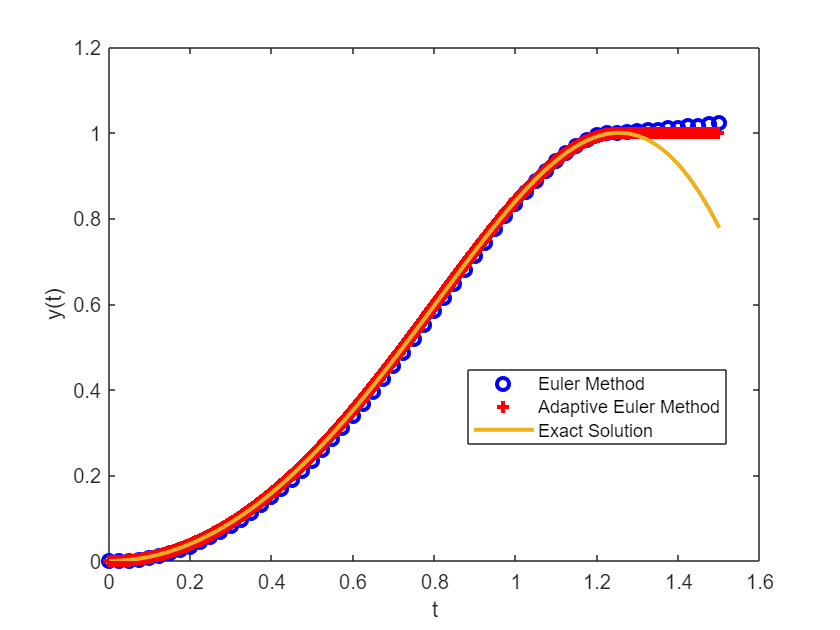

t0 = 0;
tN = 1.5;
y0 = 0;
h = 0.025;

f = @(t, y) 2 * t * sqrt(1-y^2); % (re)Define inline function
tvals = t0:h:tN; % Create t vector
euler_y = euler(f, 0, tvals); % Use euler to solve IVP using a step size of 0.01
[AEM_t, AEM_y] = AEM_solver(f, t0, tN, y0, h);

plot(tvals, euler_y, 'bo', AEM_t, AEM_y, 'r+', tvals, sin(tvals.^2), 'LineWidth', 2)
legend("Euler Method", "Adaptive Euler Method", "Exact Solution", Location="best")
xlabel("t")
ylabel("y(t)")

(c) Notice how the exact solution and the approximations become very different. Why is that? Write your answer as a comment.

% As t approaches pi/2, the value of y in both the approximations and the
% exact solution approaches 1. The Euler and AEM method both continue to
% take a step size resulting in a positive increase of y, however, this
% results in the sqrt(1-y^2) term of the ODE becoming imaginary. Since
% these solvers are not built to handle imaginary numbers, the resulting
% solutions behave oddly after t = pi/2.